# UACS : Guide de l'utilisateur

## Simulation statique d'un circuit linéaire

### Pont diviseur de tension

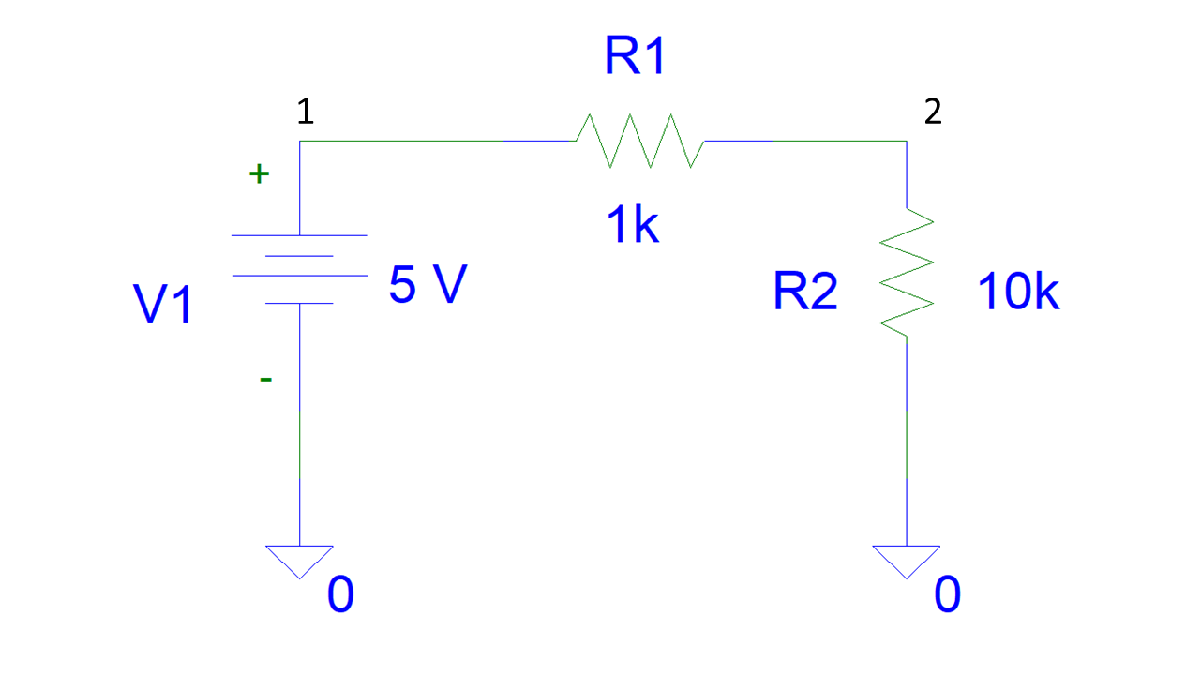

Définition du circuit :

clear
netlist={
    'R1 1 2 1e3'
    'R2 2 0 10e3'
    'V1 1 0 5'
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09
2 Resistor(s), 0 Inductor(s), 0 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}


uacs renvoie une structure sim avec sim.X correspondant au vecteur des inconnues de la formulation MNA : les potentiels des noeuds puis les inconnues de courant de la source de tension, dans l'ordre de in.V (si plusieurs sources). La *cell* sim.names donne la composition du vecteur des inconnues sim.X.

fprintf('Potentiel du noeud 1 : %g V\nPotentiel du noeud 2 : %g V\nCourant débité par la source de tension : %g A\n',sim.X(1),sim.X(2),sim.X(3))

Potentiel du noeud 1 : 5 V
Potentiel du noeud 2 : 4.54545 V
Courant débité par la source de tension : -0.000454545 A


### Circuit RC (simulation statique)

En simulation statique, la capacité est équivalente à un circuit ouvert.

clear
netlist={
    'R1 1 2 1e3'
    'C1 2 0 1e-9'
    'V1 1 0 5'
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}


sim.X

ans =     5.0000
    5.0000
   -0.0000


## Simulation temporelle d'un circuit linéaire

### Circuit RC, conditions initiales nulles

clear in
netlist={
    'R1 1 2 1e3'
    'C1 2 0 100e-9'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

118 time steps computed in 0.074925 seconds.


sim = struct with fields:
           X_t: [3×118 double]
             t: [1×118 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}


   initTRAN=CI force la condition initiale à 0 (sauf pour les capacités si une tension initiale est définie par IC=... ) pour t=0. Sinon la condition initiale = Point de fonctionnement (par défaut initTRAN=OP).

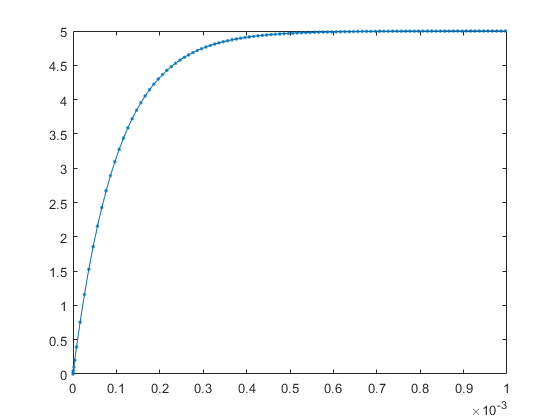

plot(sim.t,sim.X_t(2,:),'.-')

### Circuit RC conditions Vc(0)= 2 V

netlist={
    'R1 1 2 1e3'
    'C1 2 0 100e-9 IC=2'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

117 time steps computed in 0.0287415 seconds.


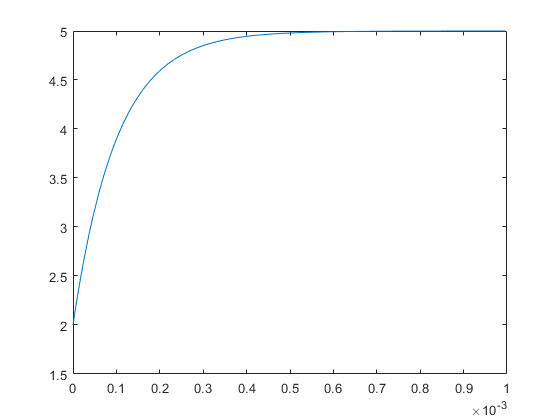

plot(sim.t,sim.X_t(2,:))

### Circuit RC-RC

clear
netlist={
    'R1 1 2 1000'
    'R2 2 0 10e3'
    'C1 2 0 100e-9'
    'C2 1 2 10e-9'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09
2 Resistor(s), 0 Inductor(s), 2 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

117 time steps computed in 0.0475142 seconds.


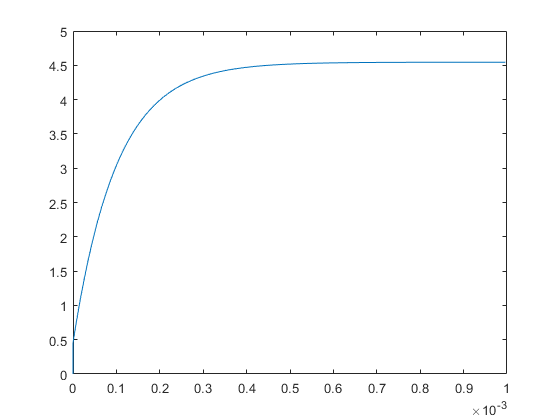

plot(sim.t,sim.X_t(2,:))

### Circuit RLC

clear
netlist={
    'R1 1 2 220'
    'L1 2 3 0.1 IC=0'
    'C1 3 0 10e-9 IC=0'
    'V1 1 0 1'
    '.tran tstop=5e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09
1 Resistor(s), 1 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 3 electrical node(s)
Transient Simulation, t0=0, tmax=0.00499987, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

616 time steps computed in 0.0875752 seconds.


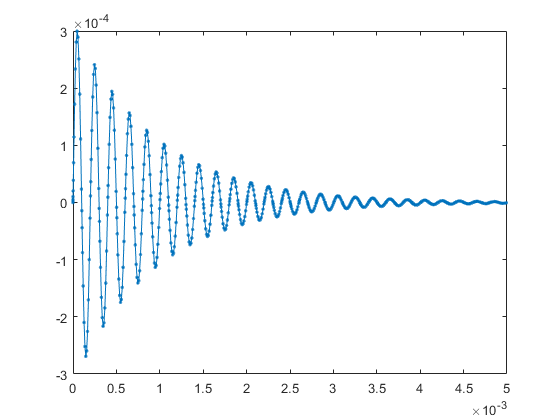

plot(sim.t,-sim.X_t(end,:),'.-')

Analyse symbolique du circuit RLC

netlist={
    'R1 1 2 220'
    'L1 2 3 0.1'
    'C1 3 0 10e-9'
    'V1 1 0 Ve'
    '.symb'
    };
sim1=uacs(netlist)

*** Analyse symbolique du Circuit ***
** fspice 2.43  ** (c) Frederic Martinez


sim1 = struct with fields:
       X: [4×1 sym]
    name: {'V(1)'  'V(2)'  'V(3)'  'I(V1)'}


Fonction de transfert :

H=sim1.X(3)/sim1.X(1)

$$H = \frac{1000000000}{s^{2}+2200\,s+1000000000}$$

Expression symbolique de la réponse indicielle :

syms s
vs=simplify(ilaplace(H/s))

$$vs = 1-{\mathrm{e}}^{-1100\,t}\,\left(\cos\left(1300\,\sqrt{591}\,t\right)+\frac{11\,\sqrt{591}\,\sin\left(1300\,\sqrt{591}\,t\right)}{7683}\right)$$

Superposition de la réponse calculée par l'expression symbolique et la simulation numérique  :

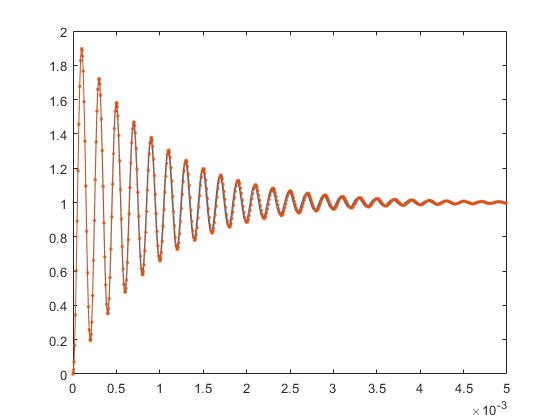

t=linspace(0,5e-3,1000);

plot(t,subs(vs),sim.t,sim.X_t(3,:),'.-')

## Circuits Non Linéaires 

### Point de fonctionnement d'un circuit Resistance - Diode en série

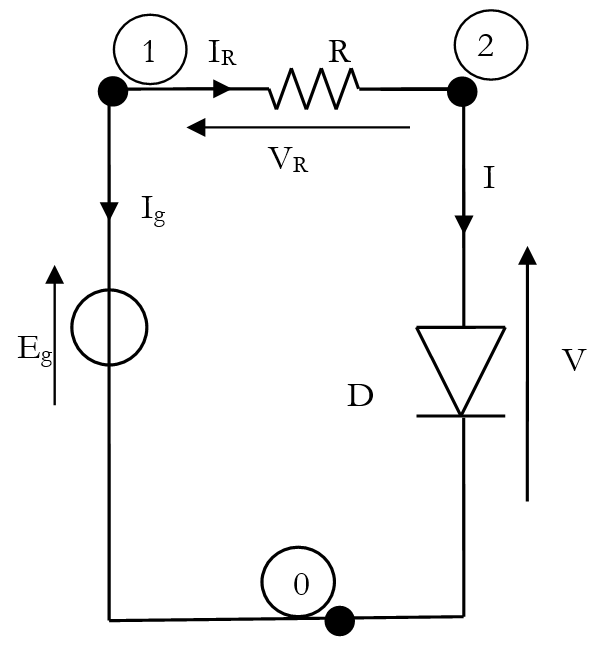

netlist={
    'V1 1 0 5'     % Générateur Eg
    'R1 1 2 1e3'   % Resistance
    'D1 2 0 1N4001'
    '.model D 1N4001 (IS1=14.11e-9 n1=1.984)'
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09
1 Resistor(s), 0 Inductor(s), 0 Capacitor(s), 1 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}


sim.X

ans =     5.0000
    0.6483
   -0.0044


La tension au borne de la diode est 0.648 V, le courant tranversant la diode est 4.35 mA.

### Evolution de la tension V et courant I en fonction de la tension Eg (0 - 10 V):

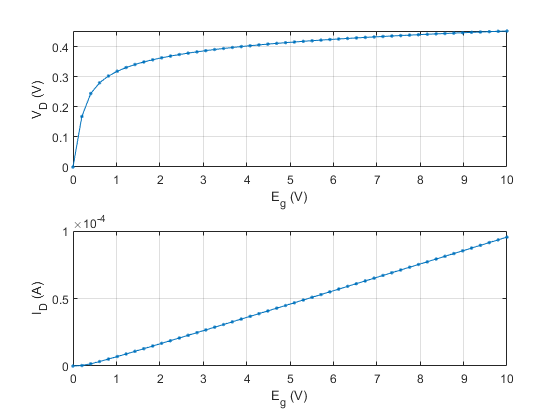

netlist={
    'V1 1 0 0'     % Générateur Eg
    'R1 1 2 100e3'   % Resistance
    'D1 2 0 1N4001'
    '.model D 1N4001 (IS1=150e-12 n1=1.5)'
    '.mute'
    };
V1=linspace(0,10,50);
for i=1:length(V1)
    netlist{1}=['V1 1 0 ' num2str(V1(i))]; % num2str convertit un double en string,
    %  puis on concatène les chaines de caractères
    sim=uacs(netlist);
    X=sim.X;
    VD(i)=X(2);Id(i)=-X(3);
end
subplot(2,1,1);plot(V1,VD,'.-');xlabel('E_g (V)');ylabel('V_D (V)');grid
subplot(2,1,2);plot(V1,Id,'.-');xlabel('E_g (V)');ylabel('I_D (A)');grid

## Amplificateur opérationnel

### Amplificateur Opérationnel : uA741 : Inverseur


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=1000 a=1 off=0)'
    
    '.tran tstop=2e-3 dtmax=.3e-4 initTRAN=CI'
    '.probe vg out'
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=3e-05, dt_min=1e-09
17 Resistor(s), 0 Inductor(s), 4 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00199995, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

343 time steps computed in 0.58506 seconds.


sim = struct with fields:
           X_t: [34×343 double]
             t: [1×343 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {2×1 cell}
      probe_id: [20 9]
         names: {1×34 cell}


Les tensions définies par .probe sont :

sim.probe_name

ans = 2×1 cell array
    {'vg' }
    {'out'}


Si on souhaite visualiser les tensions 'vg' et 'out' :

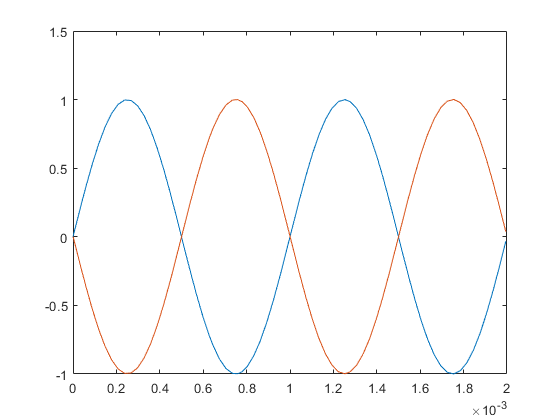

figure
plot(sim.t,sim.X_t(sim.probe_id,:))

### Amplificateur Opérationnel : uA741 : Inverseur (Saturation)


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=1000 a=15 off=0)'
    
    '.tran tstop=2e-3 dtmax=.3e-4 initTRAN=CI'
    '.probe vg out'
    'aaaa.mute'
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=3e-05, dt_min=1e-09
17 Resistor(s), 0 Inductor(s), 4 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00199995, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

671 time steps computed in 3.21936 seconds.


Si on souhaite visualiser les tensions 'vg' et 'out' :

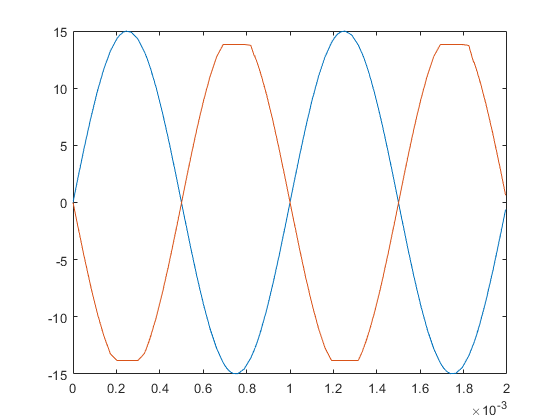

figure
plot(sim.t,sim.X_t(sim.probe_id,:))

### Amplificateur Opérationnel : uA741 : Inverseur (Slew Rate)


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=100e3 a=0.1 off=0)'
    
    '.tran tstop=2e-5 dtmax=.1e-6 initTRAN=CI'
    '.probe vg out'
    '.mute'
    };
% simulation 1 avec f=100 kHz, amplitude 0.1
sim1=uacs(netlist);
% simulation 2 avec f=100 kHz, amplitude 1
netlist{5}='V1 vg 0 sin(f=100e3 a=1 off=0)';
sim2=uacs(netlist);
% simulation 3 avec f=100 kHz, amplitude 2
netlist{5}='V1 vg 0 sin(f=100e3 a=2 off=0)';
sim3=uacs(netlist);


Si on souhaite visualiser les tensions 'vg' et 'out' :

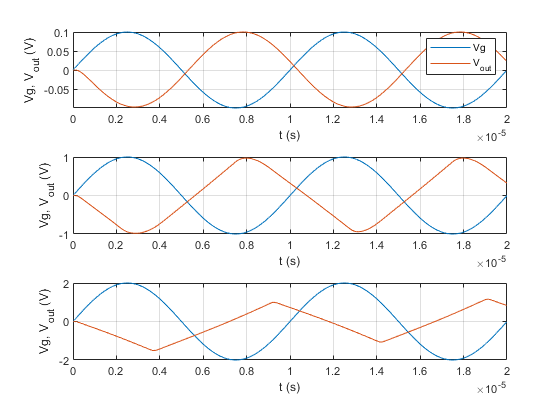

figure
subplot(3,1,1);plot(sim1.t,sim1.X_t(sim1.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid
subplot(3,1,2);plot(sim2.t,sim2.X_t(sim2.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');grid
subplot(3,1,3);plot(sim3.t,sim3.X_t(sim3.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');grid

### Amplificateur Opérationnel : uA741 : Filtre Passe Bas Salen-Key

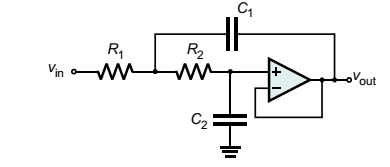

netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','out','out')
    %% Circuit
    'R1 vg A 1000'
    'R2 A e+ 1000'
    'C1 A out 63.6e-9'
    'C2 e+ 0 3.97e-9'
    'V1 vg 0 sin(f=10000 a=1 off=0)'
    
    '.tran tstop=4e-4 dtmax=1e-4 initTRAN=OP'
    '.probe vg out'
    
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=0.0001, dt_min=1e-09
16 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00039999, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale = OP
[ok]

360 time steps computed in 0.924665 seconds.


Si on souhaite visualiser les tensions 'vg' et 'out' :

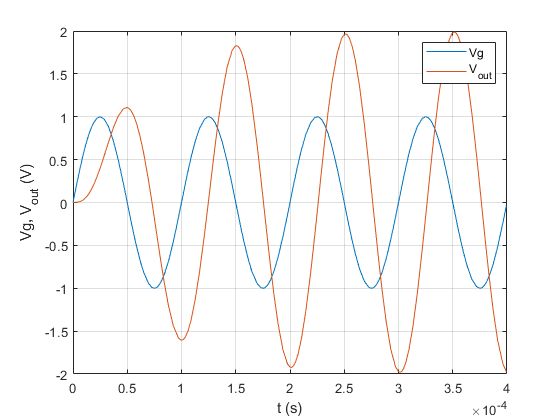

figure
plot(sim.t,sim.X_t(sim.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid

### Amplificateur Opérationnel : uA741 : Filtre Passe Bas Salen-Key, réponse à un échelon

netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','out','out')
    %% Circuit
    'R1 vg A 1000'
    'R2 A e+ 1000'
    'C1 A out 63.6e-9'
    'C2 e+ 0 3.97e-9'
    
    'V1 vg 0 1'
    
    '.tran tstop=4e-4 dtmax=1e-4 initTRAN=CI'
    '.probe vg out'
    
    };
sim=uacs(netlist);

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=0.0001, dt_min=1e-09
16 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00039999, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

514 time steps computed in 1.86604 seconds.


Si on souhaite visualiser les tensions 'vg' et 'out' :

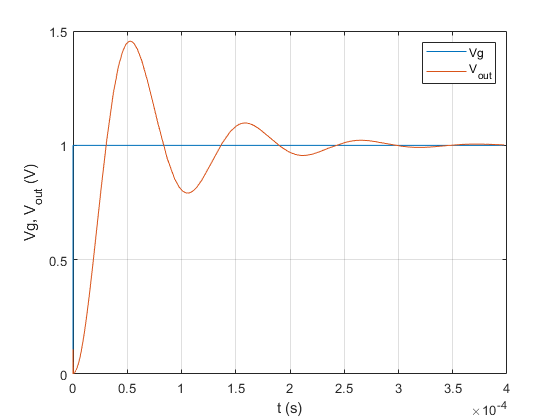

figure
plot(sim.t,sim.X_t(sim.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid

### Source de courant pour PT100

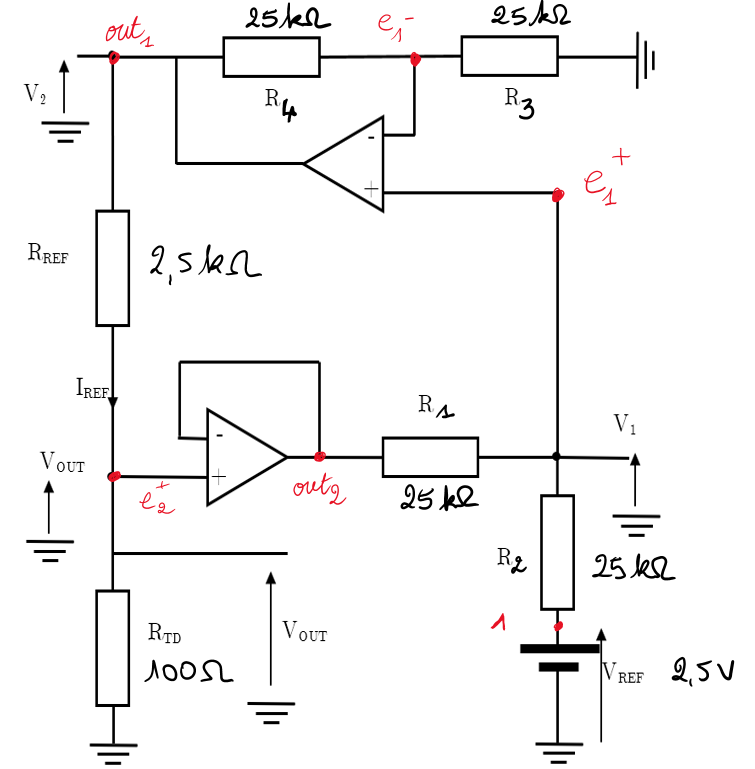

netlist={
    %Amplificateur Opérationnel uA741 1
    uA741('e1+','e1-','out1')
    %Amplificateur Opérationnel uA741 2
    uA741('e2+','out2','out2')
    %% Circuit R1 R2 R3 Rref Vref
    'R1 out2 e1+ 25e3'
    'R2 e1+ 1 25e3'
    'R3 e1- 0 25e3'
    'R4 e1- out1 25e3'
    'Vvref 1 0 2.5'
    'Rref out1 e2+ 2.5e3'
    % Resistance Thermal detector (RTD) PT100
    'Rrtd e2+ 0 100'
    '.OP'    % Simulation statique du point de fonctionnement DC
    '.probe e2+'
    
    };
sim=uacs(netlist)

Analog Circuit Simulator v1 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09
34 Resistor(s), 0 Inductor(s), 8 Capacitor(s), 10 Diode(s), 6 Current Source(s), 19 Voltage Source(s) 42 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [65×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {'e2+'}
      probe_id: 12
         names: {1×65 cell}


fprintf('Tension Vout = %g Volts \n',sim.X(sim.probe_id))

Tension Vout = 0.100073 Volts 


Avec des aplificateurs opérationnels idéaux, on obtient que Iref=1 mA. La tension Vout divisée par 1mA donne la valeur de la résistance de la RTD, et donc de la température avec Rrtd=100(1+0.00385 T). Le modèle de l'AOP UA741 dans uacs prend en compte la tension d'offset et les courant d'entrée (courants de polarisation), ceci introduit un écart sur le courant Iref traversant la RTD.

Ttheo=0;Rtheo=100*(1+.00385*Ttheo)

Rtheo = 100

Rmes=sim.X(sim.probe_id)/1e-3;
fprintf('Résistance mesurée : %g ohms, erreur relative %2.3f %% par rapport à la valeur théorique %g ohms\n',Rmes,abs(Rmes-Rtheo)/Rtheo*100, Rtheo)

Résistance mesurée : 100.073 ohms, erreur relative 0.073 % par rapport à la valeur théorique 100 ohms


Tmes=(Rmes/100-1)/0.00385;
fprintf('Temperature mesurée %g °C , valeur théorique %g °C\n',Tmes,Ttheo)

Temperature mesurée 0.190503 °C , valeur théorique 0 °C
